Using the cumulative sum of genfreq

conf=config;
PATH_TO_IDG_RAW_CLEAN_DATA = conf.PATH_TO_IDG_TRANSFORMED_DATA;
aircrafts=conf.AIRCRAFTS;
cumsumf = zeros(1,2);
for craft = 1:numel(aircrafts)
    disp(aircrafts(craft))
    a=dirCMD(fullfile(PATH_TO_IDG_RAW_CLEAN_DATA,aircrafts(craft)));
    g3 = zeros(size(a,1),1);
    g12 = zeros(size(a,1),1);
    for flight = 1:numel(a)
        data = load(a(flight));
        try
            tbl = data.tbl;
        catch ME
            tbl = data.variableName;
        end
        
        if ismember("Flight Phase",tbl.Properties.VariableNames)
            try
                sfdiff = diff(tbl.SfCount);
                sfdiff = [sfdiff ;1];
                CUMSUM1 = cumsum(sfdiff.*tbl.("GEN1FREQ"));
                CUMSUM2 = cumsum(sfdiff.*tbl.("GEN2FREQ"));
                phase51 = CUMSUM1(tbl.("Flight Phase")==5);
                g3(flight) = phase51(1);
                
                phase52 = CUMSUM2(tbl.("Flight Phase")==5);
                g12(flight) = phase52(1);
            catch ME
                continue
            end
        else
            continue
%             tbl = tbl(cumsum(tbl.("GEN1FREQ")) > 380 & cumsum(tbl.("GEN2FREQ")) > 380,:)
        end        
        
    end
    cumsumf =[cumsumf;[g3' g12']];
end

hold off
nonZeroCumSum = cumsumf(cumsumf(:,1)~=0 & cumsumf(:,2)~=0,:);
p1=plot(nonZeroCumSum(:,1),'r','DisplayName',"Gen 1 CumSum");
% p2=plot(nonZeroCumSum(:,2),'b','DisplayName',"Gen 2 CumSum");
ylabel("nonZeroCumSum of gen freq")
yline(quantile(nonZeroCumSum(:,1),0.25))
% legend([p1 p2])
legend

meancumsum1 = mean(nonZeroCumSum(:,1))
meancumsum2 = mean(nonZeroCumSum(:,2))

Using the duration

conf=config;

No normalisation data detected. config.dataMinMax attribute empty


PATH_TO_IDG_RAW_CLEAN_DATA = conf.PATH_TO_IDG_RAW_CLEAN_DATA;
aircrafts=conf.AIRCRAFTS;
dur = zeros(1,4);
parfor craft = 1:numel(aircrafts)
    disp(aircrafts(craft))
    a=dirCMD(fullfile(PATH_TO_IDG_RAW_CLEAN_DATA,aircrafts(craft)));
    
    g3 = zeros(size(a,1),2);
    g12 = zeros(size(a,1),2);
    for flight = 1:numel(a)
        data = load(a(flight));
        tbl1 = data.gen1;
        tbl2 = data.gen2;
        tbls = {tbl1 tbl2};
        
        for gen = 1:numel(tbls)
            tbl = tbls{gen};
            if ismember("FlightPhase",tbl.Properties.VariableNames)
                try
                    phase3 = tbl(tbl.("FlightPhase")==3,:);
                    g3(flight,gen) = phase3.Time(1)/tbl.Time(end);
                    
                    phase12 = tbl(tbl.("FlightPhase")==11,:);
                    g12(flight,gen) = (tbl.Time(end) - phase12.Time(end))/tbl.Time(end);
    
                    if g3(flight,gen) < 0 || g12(flight,gen) < 0 
                        disp("Suspicious table found!")
                        disp(a(flight))
                        keyboard
                    end
                catch ME
                    continue
                end
            else
                continue
            end        
        end
    end
    try
        dur =[dur;[g3 g12]];
    catch ME
        disp(ME.message)
        disp(size(g3))
        
        disp(size(g12))
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).
HS-ABA
HS-ABC
HS-ABI
HS-ABD
HS-ABJ
HS-ABF
HS-ABM
HS-ABP
HS-ABG
HS-ABT
HS-ABH
HS-ABU
HS-ABV
HS-ABZ
HS-ABX
HS-BBR
HS-BBS
HS-BBI
HS-BBU


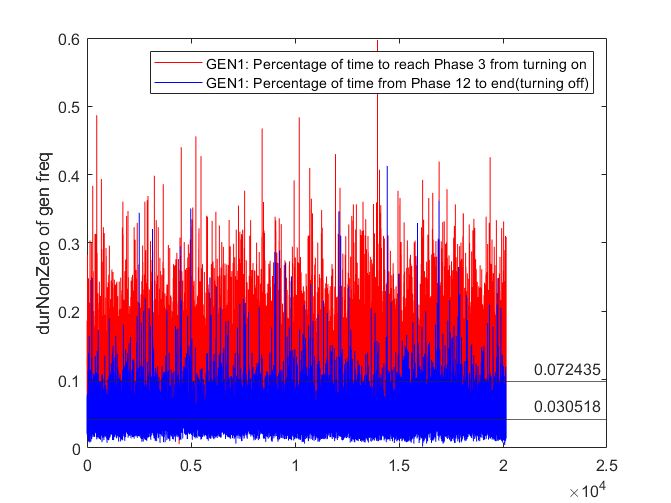

durNonZero = dur(dur(:,1)~=0 & dur(:,3)~=0,:);
hold off
p1=plot(durNonZero(:,1),'r','DisplayName',"GEN1: Percentage of time to reach Phase 3 from turning on");
hold on
p2=plot(durNonZero(:,3),'b','DisplayName',"GEN1: Percentage of time from Phase 12 to end(turning off)");
ylabel("durNonZero of gen freq")
yline(quantile(durNonZero(:,1),0.5),'-',string(quantile(durNonZero(:,1),0.25)))
yline(quantile(durNonZero(:,3),0.5),'-',string(quantile(durNonZero(:,3),0.25)))
legend([p1 p2])

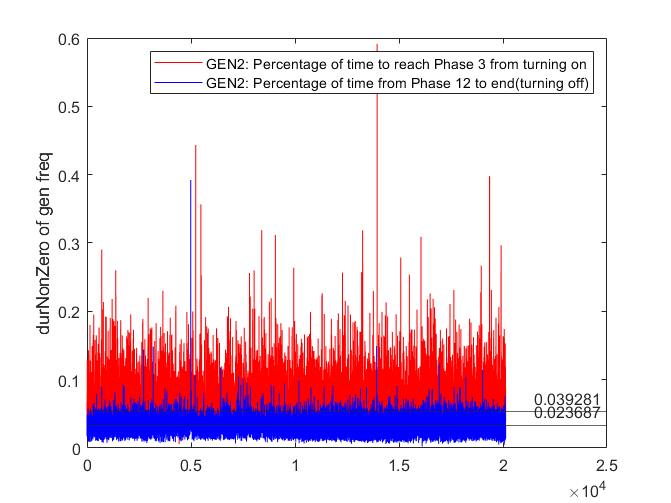

durNonZero = dur(dur(:,2)~=0 & dur(:,4)~=0,:);
hold off
p1=plot(durNonZero(:,2),'r','DisplayName',"GEN2: Percentage of time to reach Phase 3 from turning on");
hold on
p2=plot(durNonZero(:,4),'b','DisplayName',"GEN2: Percentage of time from Phase 12 to end(turning off)");
ylabel("durNonZero of gen freq")
yline(quantile(durNonZero(:,2),0.5),'-',string(quantile(durNonZero(:,2),0.25)))
yline(quantile(durNonZero(:,4),0.5),'-',string(quantile(durNonZero(:,4),0.25)))
% yline(quantile(durNonZero(:,4),0.5))
legend([p1 p2])

pd = fitdist(durNonZero(:,1),'Normal');
y = normpdf(durNonZero(:,1),pd.mu,pd.sigma);
plot(durNonZero(:,1),y,'r','DisplayName',"Percentage of time to reach Phase 5")
hold on
pd = fitdist(durNonZero(:,2),'Normal');
z = normpdf(durNonZero(:,2),pd.mu,pd.sigma);
plot(durNonZero(:,2),z,'b','DisplayName',"Percentage of time from Phase 9 to end");
% legend([p1, p2])